water60xFluoImMask_ys

Shuai Yang 

2021/12/28

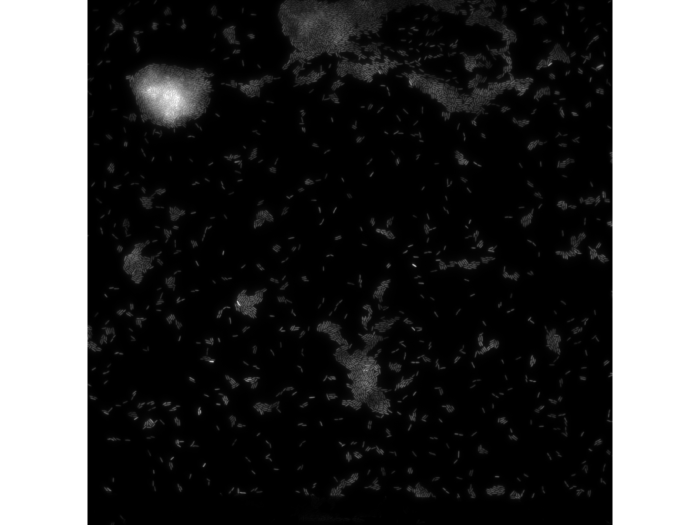

I0 = imageCyOFP00001;
% I0 = rescale(double(I0))*255;
% I0 = uint8(I0);

edgeFilter = (ones(5,5)).*-1;edgeFilter(3,3) = 24;%created edgefilter

% I1 = imgaussfilt(I0, 1);
% imshow(I1,[])
% I1 = imfilter(I1,edgeFilter);
% imshow(I1,[]);
% I1 = imgaussfilt(I1, 1);
% imshow(I1,[]);
% 
% level = graythresh(I1);
% I2 =imbinarize(I1,level/2.2);
% imshow(I2,[])
% 
% bw = edge(I1-600,'log',0);
% imshow(bw)
% bw1 = imclearborder (bw);
% bw1 = imfill( bw1,'holes');
% imshow(bw1)



fluoImage = I0;
fluoImMask = false(size(fluoImage));

[~,BG] = substractBackGround(I0);%获得背景数值 backGround signal
small = BG;
big = ImBigSignalGet(I0);

sigma =  1;
I1 = imgaussfilt(I0-BG, sigma);
imshow(I1,[])

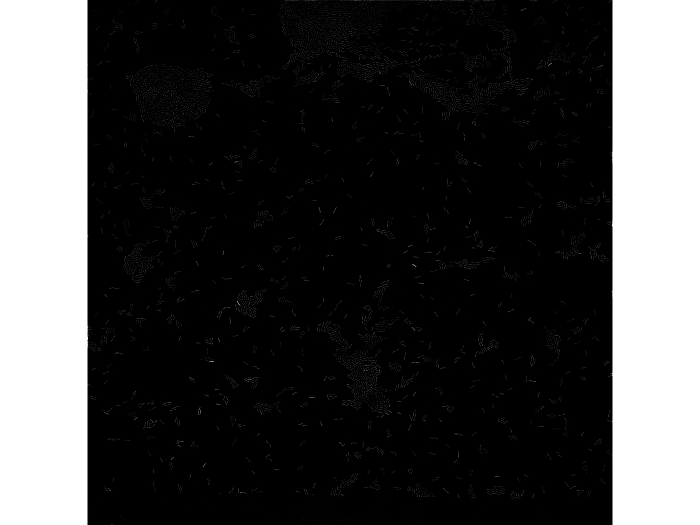

I1 = imfilter(I1,edgeFilter);
imshow(I1,[]);

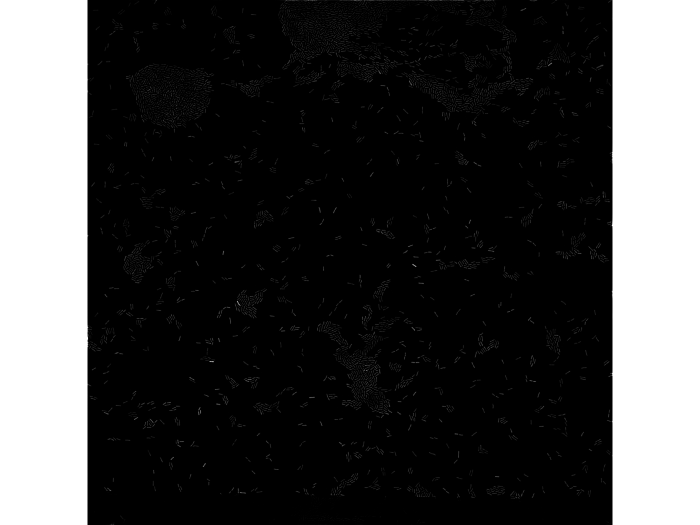

I1 = imgaussfilt(I1, sigma);
imshow(I1,[]);

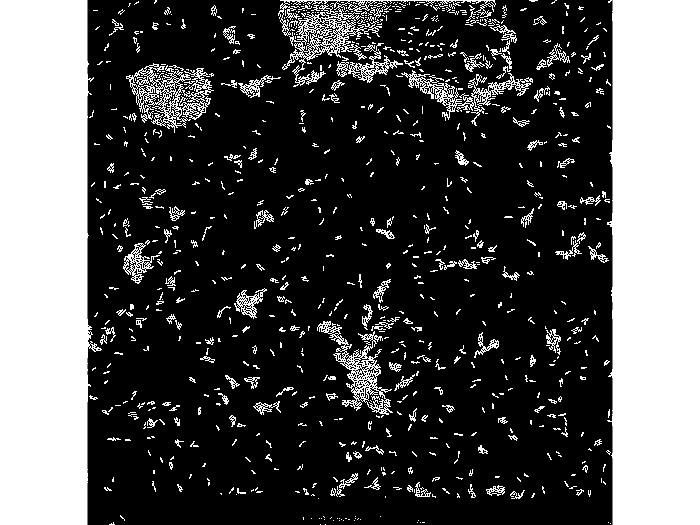


level = graythresh(I1);
I2 = imbinarize(I1,level/2.6);
imshow(I2,[])

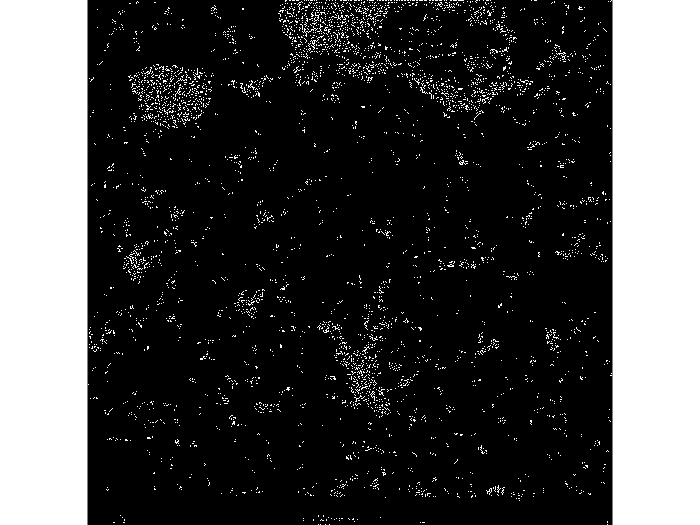



% % use a threshold to find where the cells are
thre = prctile((small:big),6); % 百分位数

bw = edge(I1-thre,'log',0);
imshow(bw)

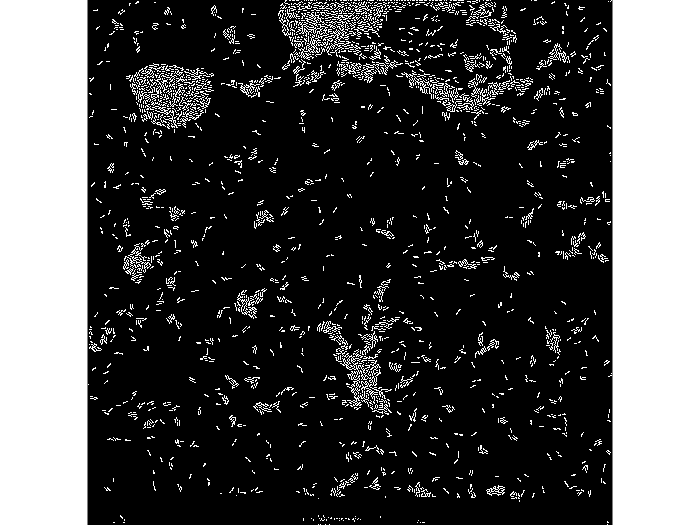

bw1 = imclearborder (bw);
bw1 = imfill( bw1,'holes');
imshow(bw1)

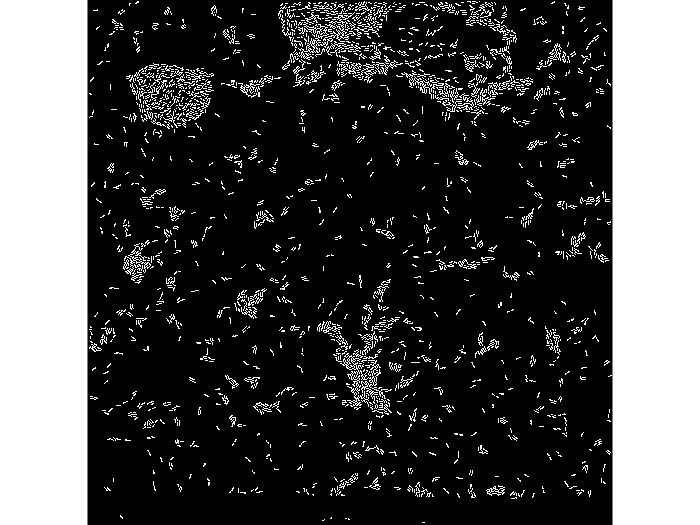

bw1 = bwareaopen( bw1, 40, 4);
imshow(bw1)

% % I2 = imgaussfilt(I0,2);
% % 
% I2 = I0;
% % 
% x = double(I2);
% s = sort(x(:));
% % small = s(25);
% % case for imdrift correction pixelvalue = 0
% small = BG;
% %     big= s(end-25);
% signal = s-(small+40);% 40 could change
% signal(signal<=0) = [];
% if isempty(signal)
%     return
% end
% signal = signal+(small+40);
% %     big = signal(round(length(signal)*0.93));% 0.93 could change
% big = ImBigSignalGet(signal);
% rescaled = (x - small)/(big - small);
% rescaled(rescaled<0) = 0;
% I3 = uint16(10000*rescaled);
% imshow(I3,[])
% 
% % use a threshold to find where the cells are
% I3 = I3 - 480;
% imshow(I3,[])
% bw = edge(I3,'log',0);
% 
% bw1 = imclearborder (bw);
% bw1 = imfill( bw1,'holes');
% imshow(bw1)
% bw1 = bwareaopen( bw1, 40, 4);
% fluoImMask = bw1;
% imshow(bw1)
% %% sub function

function [big_signal] = ImBigSignalGet(signal)
% 荧光图像mask获得用到的子函数
% 用于荧光图像中大光强信号的获得Shuai Yang 2021.10.15

signal = sort(double(signal(:)),'descend' );
pixelSpace = 1:100:numel(signal);%每100个pixel计算平均值
% case for <100 pixel
if numel(pixelSpace) < 2
    big_signal = mean(signal(:));
    return
end

M = zeros(numel(pixelSpace)-1,1);

for i = 1:numel(pixelSpace)-1
    M(i) = mean(signal(pixelSpace(i):pixelSpace(i+1)));
end

if numel(M) < 5
    big_signal = M(1);
    return
end

n = 5;
CV = std(M(1:n))/mean(M(1:n));
while CV > 0.03 % equal CV > 0.03 && n >= 1
    n = n-1;
    CV = std(M(1:n))/mean(M(1:n));
end

if n == 1
    big_signal = mean(M(1:5));
else
    big_signal = mean(M(1:n));
end
end